# IntroductionToMATLAB

*Author D. Carlsmith*

This MATLAB Live Script provides an introduction to MATLAB command syntax, files, numbers, characters, strings, symbols, operators, functions, arrays, precision, errors, plots, and symbolic algebra and symbolic calculus. It also teaches how to send secret messages and how to twirl images in 3-d.

To prepare, place this script file in a default (for you) MATLAB work folder. Copy a jpg image file to that folder and give it the name IMG-1.jpg you find below or change the script to point to the name of your file. 

Then launch MATLAB. Load this file into your MATLAB environment Live Editor by double-clicking it in the MATLAB file browser (upper left pane). Click on it in the upper-right Live Editor pane where it will appear under a tab.

The script is broken into individually executable interactive sections. You can click the green `Run` arrow to run the whole thing sequentially but you will get an error from a section where you need to change a filename to one of your own if you have not renamed your file or changed the script correctly.

Use the button on the right to set the output and code in-line rather than having the output in a separate column. Then run individual sections by clicking in the section body and then clicking the vertical blue bar at the left of a section. (If you click and see a green (debug stop point) arrow, click the green arrow to dismiss it.) Or click the "Run section" button at the top of the screen if you see it. (Set MATLAB preferences to add the Run section button if necessary.)

As you go along, observe values of variables in the workspace pane. The values may also display if you mouse over them in the script. Test the commands yourself in the Command Window but using different variable names to not interfere with the script. You can also alter or add code commands in a section and rerun the section to see the effect. You may want to save a backup copy of the script. 

As you encounter a new command or function and want to learn more, type it or copy it into the help search field at the top of the MATLAB main window, and hit 'enter' to open a help window, or into the search field of an already open help window to create a new help tab. Or use google with the search string beginning with the word MATLAB and create tabs in a browser.

## Numbers and basic commands

MATLAB recognises integers, real numbers, complex numbers, arrays and more elaborate data types. Type the following into the Command Window to emulate this script.

5

ans = 5

MATLAB created a default variable `ans`, set its value to the known (to MATLAB) number 5, and echoed the result. 

Of course, we can add, subtract, multiply, and divide (+-*/) numbers.

5+4;
x=5*4

x = 20

A trailing semicolon suppresses expression of the result of the command. So the `5+4;` produced no output but it assigned value 9 to the default variable `ans`. (You can see `ans` and its value in the workspace.) The 2nd command `x=5*4` created the variable x and set its value to the product of 5 and 4. There was no semicolon at the end of the command so MATLAB echoed what it accomplished.

Create a variable x and assign it a numerical value and add a comment. 

x =            5 % Everything after a % is ignored.

x = 5

% Note the 2nd "%" above did not end the comment.

MATLAB completes the command and echos the result, ignoring the white spaces and comment.

Separate multiple commands on one line with `;` (no output) or `,` (output). Multiple commands on a line are discouraged, as they make the code unreadable, unless the commands are quite short.

x=5; y=6,z=7;% short enuf to be single-line readable

y = 6

MATLAB is designed for arrays of numbers. More on that later. We can make an example array (a row vector) using brackets and commas.

a=[5,4,3,2,1]

a =      5     4     3     2     1


and refer to its elements by position like this

a(2)

ans = 4

and we can autogenerate a longer vector containing, say, 100 thousand elements, like this

a=[1:100000]; % Do not output the result!
length(a)

ans = 100000

a(1),a(99550)

ans = 1

ans = 99550

Continue long commands on to subsequent lines with a terminal ellipsis (...). Notice the commenting in what follows.

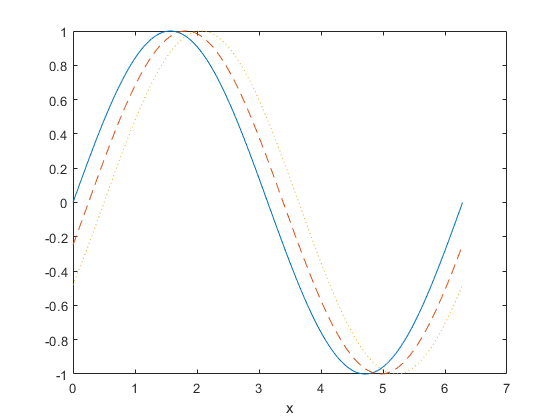

% Make array/sequence of 101 numbers between 0 and pi
% using the xmin:increment:xmax construction 
x = 0:pi/100:2*pi;
% Make a new figure window
figure
% Plot function values y =f(x)at all of the x values 
% as tiny points and link the (x,y) points with 
% solid(default), dashed, and dotted lines. 
% Repeat for various functions. Supply a label.

plot(x,sin(x),x,sin(x-0.25),'--',...
    x,sin(x-0.5),':');xlabel('x'); 

## Complex numbers

MATLAB supports complex numbers as well as real numbers. Complex numbers are (more than) twice as powerful as real numbers. The symbol `i` stands for sqrt(-1). Engineers use the symbol j for sqrt(-1) so MATLAB reserves both `i` and `j but uses `i` in output.`

i,j

ans =   0.000000000000000 + 1.000000000000000i


ans =   0.000000000000000 + 1.000000000000000i


To add two complex numbers, add the real and imaginary parts.

x=1+i*3,y=2+j*4,

x =   1.000000000000000 + 3.000000000000000i


y =   2.000000000000000 + 4.000000000000000i


z=x+y

z =   3.000000000000000 + 7.000000000000000i


The product of complex numbers is the sum of the products of all the parts.

z=x*y

z = -10.000000000000000 +10.000000000000000i


Extract real and imaginary parts as real numbers.

real(z), imag(z)

ans =    -10


ans =     10


The complex conjugate operation command `conj` reverses the sign of the imaginary part.

zc = conj(z)

zc = -10.000000000000000 -10.000000000000000i


A complex number can represent a 2-d vector. Think of the real and imaginary parts as x and y components of a vector with 1 as a unit vector along x and i as a unit vector along y. We can express general results with numbers or symbols. (More on symbols later.) 

syms x y z theta
z=x+i*y 

$$z = x+y\,\mathrm{i}$$

The absolute magnitude sqrt(z*conj(z) is the length of the vector

abs(z), sqrt(simplify(z*conj(z))),abs(1+i)

$$ans = \left|x+y\,\mathrm{i}\right|$$

$$ans = \sqrt{\left(\frac{{\left|x\right|}^{2}}{x}-\frac{{\left|y\right|}^{2}\,\mathrm{i}}{y}\right)\,\left(x+y\,\mathrm{i}\right)}$$

ans =    1.414213562373095


The ratio y/x is the tangent of the polar angle and can be supplied by the command `angle`.

theta=angle(z), theta=angle(1+i)*180/pi

$$theta = \text{atan2}\left(y,x\right)$$

theta =     45


## Characters

A character is a member of a class of data representing the alphabet (in the default english locale, other characters elsewhere). Internally, a character corresponds to a number defined by the UTF-16 unicode standard ( [https://en.wikipedia.org/wiki/Unicode](https://en.wikipedia.org/wiki/Unicode) ) . Creating a variable with type character tells MATLAB to treat it as a character in appropriate circumstances, not as a number.

% Use char to create a character with UNICODE 70
a= char(70)

a = 'F'

MATLAB responds with a result in single quotes to indicate the `char` function has returned a character type result and MATLAB has assigned it to the variable a. Single quotes tell the MATLAB command parser that the thing between the single quotes is to be interpreted as a character, so we create characters usually as follows.

a='F' 

a = 'F'

 MATLAB created the character 'F' (an integer code underneath) corresponding to the letter F and assigned it to the variable that we happened to name `a`. That is hard to get one's head around. It takes practice and experiment. The variable names don't necessarily disclose their type. A more transparent name choice would be something like

charF='F';

A word has many characters. The following makes an array of characters.

a='Firstname' % an array of characters of length 9

a = 'Firstname'

MATLAB created an array (a vector) `a` of length 9  characters. Each character is individually addressable using an array position index. 

length(a) % length(x) gives the length of an array

ans = 9

a(1)% first letter

ans = 'F'

## How to send encrypted messages

We can trick MATLAB into telling us the unicodes by adding zero to each element of the array. Adding incompatible data types only works if there is a operator-data precedence rule. Here, when adding a character and a number, the rule is to replace a character by its numerical code, add that to the number in the usual sense, and output a number, not a character. We will add a double-type number zero to a character array so the output will be a double type array, with one array entry per character.

a='Hi mom. Just starting class!' % a character array

a = 'Hi mom. Just starting class!'

a+0 % produces an array of doubles as 0 is treated as a double by default

ans =     72   105    32   109   111   109    46    32    74   117   115   116    32   115   116    97   114   116   105   110   103    32    99   108    97   115   115    33


Here comes another trick. Add 1 to the array of doubles to make an array b of numeric codes (of type double) incremented by 1.

b=a+1 % b is an array of doubles with incremented code values

b =     73   106    33   110   112   110    47    33    75   118   116   117    33   116   117    98   115   117   106   111   104    33   100   109    98   116   116    34


Convert `b` back to characters and it looks unintelligible. 

b=char(b) 

b = 'Ij!npn/!Kvtu!tubsujoh!dmbtt"'

Send/text-message or upload to your discussion group or to Piazza that output string for your group partner to decrypt.

Your partner just wrote back! The message your partner sent is 'Tp!hsfbu"!Cvu!J!bn!opu!zpvs!npn"' Let's decode it.

Treat the message as a character array. Convert the character to an array of number codes

b='Tp!hsfbu"!Cvu!J!bn!opu!zpvs!npn"'+0

b =     84   112    33   104   115   102    98   117    34    33    67   118   117    33    74    33    98   110    33   111   112   117    33   122   112   118   115    33   110   112   110    34


Decrement the codes

b=b-1

b =     83   111    32   103   114   101    97   116    33    32    66   117   116    32    73    32    97   109    32   110   111   116    32   121   111   117   114    32   109   111   109    33


Regenerate the characters that were sent by your partner.

char(b)

ans = 'So great! But I am not your mom!'

## Strings

A string is an array, the elements of which are character arrays (words). We can assemble character arrays into strings by concatenation using the comand `strcat`.

a='Firstname';b='Lastname';% character arrays
c= strcat(a,',',b) % concatenation of 3 character arrays

c = 'Firstname,Lastname'

String concatenation is useful to, for example, build a full path to a file on your local computer or on the internet.

**Navigate if necessary to make your current folder in MATLAB your default MATLAB working folder before proceeding.  Look at the directory of the current folder in the file browser of the MATLAB GUI/application to verify. Copy an .jpg image to the folder to display if you have not done so.**

Use the function `pwd` to get the full path to your current folder/working directory. (pwd is short for print working directory, a unix command name)

presentfolder = strcat(pwd, '\Physics 247\Week 1\Intro to Matlab')

presentfolder = 'C:\Users\maxdesktop\MATLAB Drive\Physics 247\Week 1\Intro to Matlab'

Define a character array giving the name of an image file in your current folder. (Again, copy a jpg image file to your current folder if needed.) You can emulate this script

imagefilename='IMG - 1.jpg'

imagefilename = 'IMG - 1.jpg'

Create a full path to the image file with a slash indicating the file is a member of the folder

fullimagefilename=strcat(presentfolder,'\',imagefilename)

fullimagefilename = 'C:\Users\maxdesktop\MATLAB Drive\Physics 247\Week 1\Intro to Matlab\IMG - 1.jpg'

Read in the image into an array *I* . Do NOT output the array to the screen (include the semicolon at the end of the command) as the array is something like a 4032x3024x3 uint8 array (first two numbers are pixel width and height, the 3rd is for 3 colors) and it takes a while to write that many values on your computer screen.

I = imread(fullimagefilename); % definitely don't print

Just view a 5x5 corner of the red values. These values are uint8 integers, integers in the range constructable with 8-bits, i.e. 0 to 255.

We can use the 1:5 construction to indicate the range of indices 1 through 5, set the 3rd index value to 1 meaning red, and get what we need as follows.

I(1:5,1:5,1)

ans = 5×5 uint8 matrix
   14   13   12   16   23
   11   20   23   18   16
   16   13   15   19   18
   12   14   15   13   15
   16   12   13   17   20


Show the image file

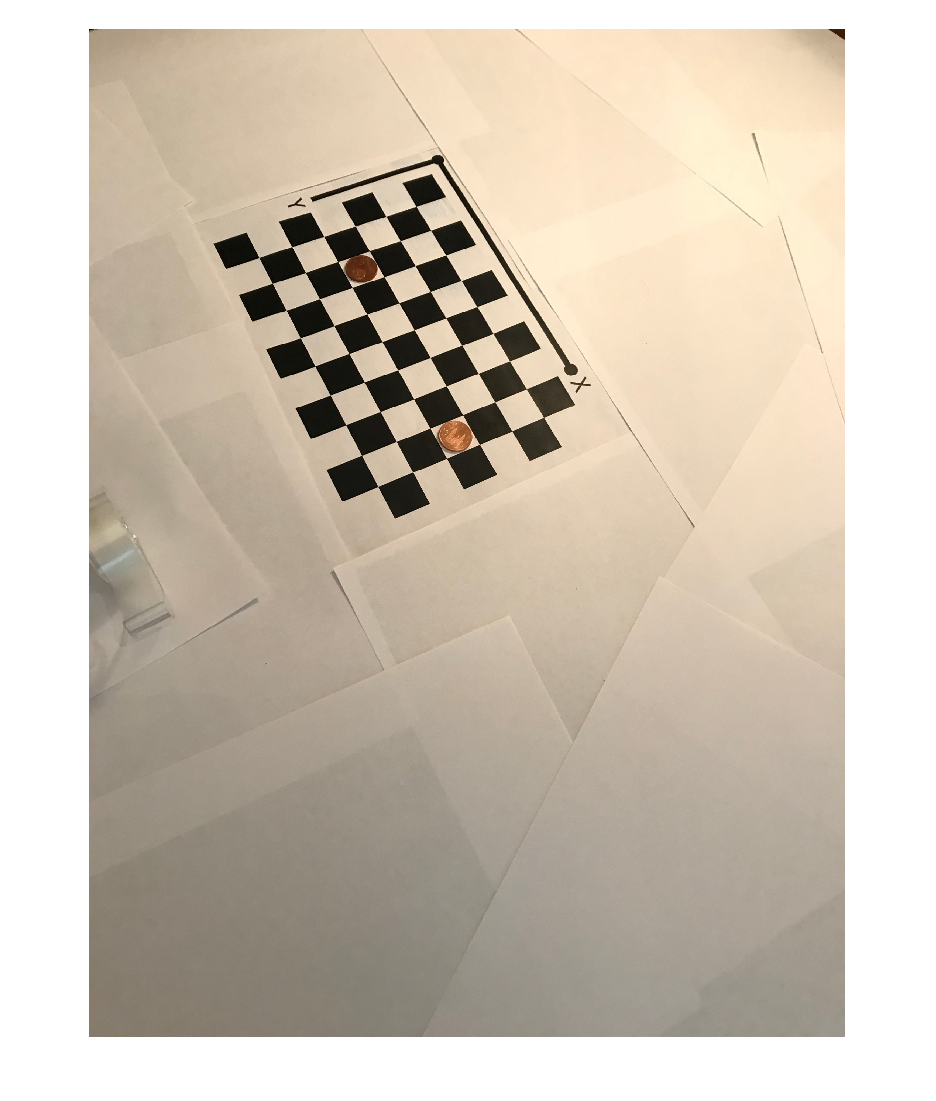

imshow(I) % open a window for display

Try opening the image that appear in this Live Script in its own window using the arrow option that appears when you mouse over the top right corner of the figure in the Live Script output. In the independent figure window that appears, for fun, select tools=>rotate 3d. Spin the image around as if it were printed out and you looking at it from various perspectives.

## Paths

Find the full path to the file `pathdef.m` which MATLAB uses as a list of folders to search through when finding functions and files, the full foldernames separated by colons. You can open that in a text editor (after saving a backup copy!) to take a look. Note that on an OSX machine, an App is actually a folder containing a whole hierarchy of subfolders. Using Finder, to drill into an app, control-click the name or icon and select "show package contents." This rigamarole is designed to prevent people from messing up app files needed for apps to run successfully.

which pathdef.m

C:\Program Files\MATLAB\R2020a\toolbox\local\pathdef.m


Check what paths MATLAB knows about (stored in `pathdef.m) by `using the `path` command, storing the result as `presentpath`.

presentpath=path; % Don't output! It's a long list.
length(presentpath) % Told you so.

ans = 37181

Add the path to the current folder (`presentfolder`) to the top of the path list in `pathdef.m `just in case it wasn't on the path list using `addpath`.

addpath(presentfolder);

## MATLAB function library

A variety of familiar mathematical functions are predefined to work with real and imaginary variables, and also with arrays. The sin of a complex number is defined by the normal Taylor series. The sin of a 2d array (matrix) requires we can square and cube the matrix. More on that later.

x= 5; z= 1+i*2;
sin(x),sin(z)

ans = -0.9589

ans = 3.1658 + 1.9596i

exp(i*x),exp(z)

ans = 0.2837 - 0.9589i

ans = -1.1312 + 2.4717i

## Operations with numbers and solving homework exercises

Here are some everyday operations

x=5,y=6,z=x/y,w=x*z; 2^10, sqrt(2)

x = 5

y = 6

z = 0.8333

ans = 1024

ans = 1.4142

The output from w=x*z was suppressed. But w can be seen to have been created in the workspace and we can type its name without the terminal semicolon to see its value. 

w

w = 4.1667

Use disp(w) to supress the name in displaying a long list of things

disp(w)

    4.1667



Evaluate a formula to solve a homework exercise without making the usual mistakes in keeping track of things when using a hand calculator using MATLAB.

a = 5; b = pi; c= 3; d=1;
(a^2+c)*sin(5.3*b)*exp(-a/d)% random formula

ans = -0.1526

We will talk about sig figs later.

Repeat for 10 values of a, say 1,2,...,10, and toss in a plot of y vs a with variable and metric units on the axis labels with a different value of d. [Note, we vectorize `a `into an array and  put . before each operator * or ^ to tell MATLAB to operate on each element of the array and return an array.]

a=[1:10]; d=2; 
y=(a.^2+c).*sin(5.3*b).*exp(-a/d)

y =    -1.9628   -2.0833   -2.1662   -2.0803   -1.8594   -1.5709   -1.2704   -0.9928   -0.7549   -0.5615


Use * as the point symbol and connect points with dash-dot lines just to illustrate the capabilities of the `plot` command. And add a label and note the LaTeX notation superscript is respected.

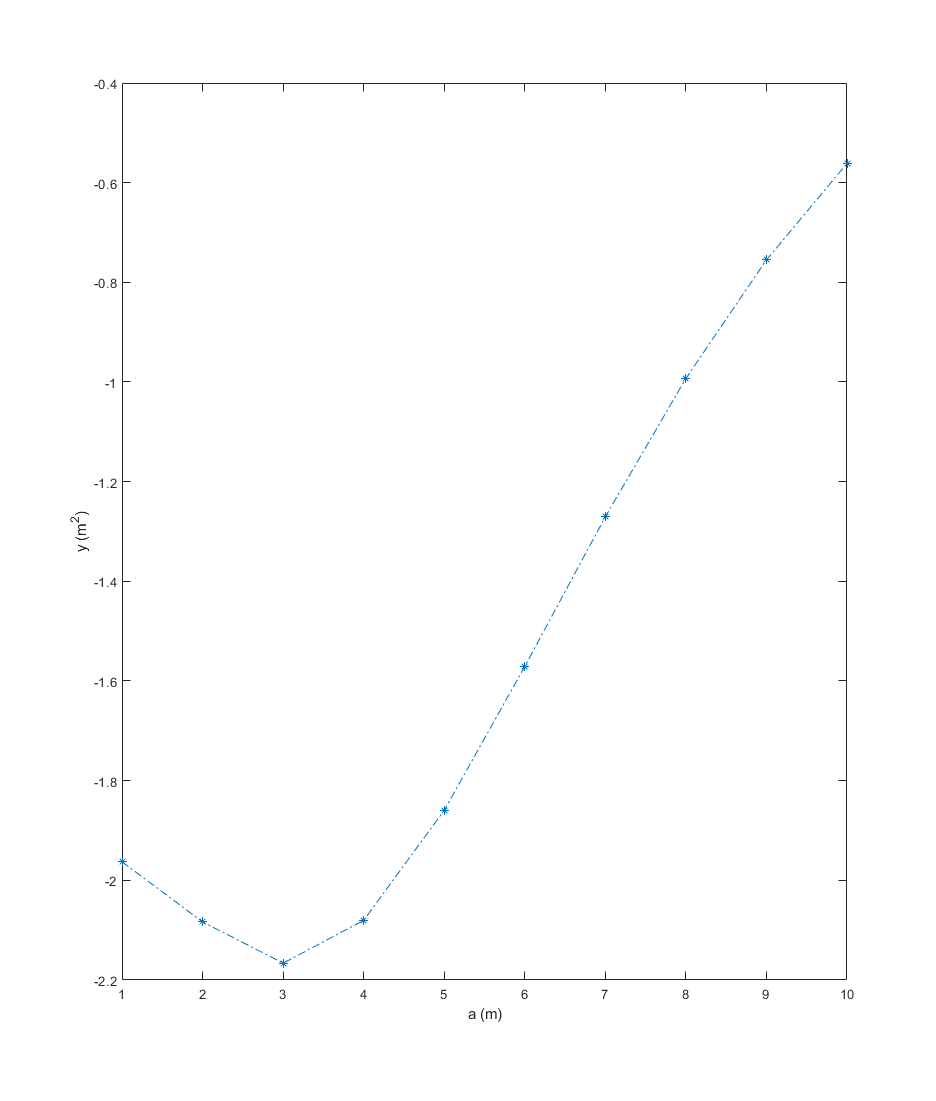

plot(a,y,'*-.');xlabel('a (m)'),ylabel('y (m^2)')

## Predefined quantities

Predefined quantities include numbers,  i=j=sqrt(-1), the function pi, and common functions like sin(x), exp(x). Don't overwrite these names. Don't use i and j as names for variable integer indices, a common practice in math and physics textbooks! If you redefine a predefined thing, `clear` will fix the problem

pi, i,j,pi=2,clear pi, pi, ,w

ans = 3.1416

ans = 0.0000 + 1.0000i

ans = 0.0000 + 1.0000i

pi = 2

ans = 3.1416

w = 4.1667

To clear out all variables and reset predefined ones, use `clearvars.` You will see the workspace empty.

clearvars

## MATLAB errors

% clearvars
% a=1;b2;c=3;d=4;

Uncomment the preceding two lines and run the section. Then fix it or recomment since the error within it will prevent further execution of the live script.

I meant to type b=2, not b2, and only the command a=1 will suceed, as you can see in the workspace. MATLAB aborts the rest of the line of code. It may scan a whole section and refuse to execute any of it it if detects an error like this. It didn't know what to do with the command b2 since no variable of that name exists. It could have existed and then MATLAB would have happy set the default variable ans to the value of b2, output nothing (there is a semicolon), and merrily moved on. You might not know womething was wrong until later when you tried to reference the variable b and subsequently produced a spurious result. Ouch!

To catch this kind of error, test EACH line of code as you write it. Make sure it does what you hope it does.

## Precision

Variable types include the exact integer types  int8, int16,...int64, and floating point types (number plus exponent) single (byte) and double. The default representation of numbers is finite but selectable in units of bytes=8 bits. The smallest relative accuracy is called eps

eps, 1+eps, 1+5*eps

ans = 2.2204e-16

ans = 1.0000

ans = 1.0000

`pi` is a function that always returns a double. The number of digits actually displayed for all numeric variables is set with the `format` command which offers many options.

format short 
pi

ans = 3.1416

format long
pi

ans =    3.141592653589793


The sin function evaluated at pi is not exactly zero due to the default finite precision of the representation of pi.

sin(pi)

ans =      1.224646799147353e-16


The largest floating point numbers representable may displayed using the dedicated command `realmax`.

realmax('single'),realmax('double')

ans = single
   3.4028235e+38


ans =     1.797693134862316e+308


Largest integers representable are displayed with `intmax`.

intmax('int8'),intmax('int32'),intmax('uint64')

ans = int8
   127


ans = int32
   2147483647


ans = uint64
   18446744073709551615


Points of reference on precision: A typical digital camera produces a digital image comprised of three arrays of unsigned 8 bit integers from 0 to 255, each representing a quantized value of the integral of light intensity over a shutter-determined integration interval of e.g. 10 ms.  For a table of hand-held calculator accuracies, see [http://www.rskey.org/~mwsebastian/miscprj/models.htm](http://www.rskey.org/~mwsebastian/miscprj/models.htm) .

To see how accurate a double is, let's convert pi (defaults to double) to a character string using num2str asking for some large number of characters

numsigdigits=1000

numsigdigits =         1000


pistring=num2str(pi, numsigdigits)

pistring = '3.141592653589793115997963468544185161590576171875'

and find out how many characters the conversion finds

length(pistring)

ans =     50


Looks like pi is represented by 50 digits.

Arbitrary variable precision is supported. Let's set the number of significant digits using variable precision to a large number and compute pi to that many sig. figs.

digits(200)% set 200 digit precision
vpa(pi) % not so long we can't display it!

$$ans = 3.141592653589793238462643383279502884197169399375105820974944592307816406286208998628034825342117067982148086513282306647093844609550582231725359408128481117450284102701938521105559644622948954930382$$

Go for broke... How about 50 thousand digits?

digits(50000)% set 50000 digit precision
a=vpa(pi);% declare pi vpa but don't display!!
c=char(a);% convert to character string
length(c)

ans =        50001


Let's hunt in the 50000 digits for the sequence 14159 and list where the number occurs. Note pi=3.14159.... and the decimal point counts in the character string.

strfind(c,'14159')% find occurances of '14159'

ans =            3        6957       45236


strfind(c,'12345')% find occurances of '12345' in pi

ans =        49704


strfind(c,'53706') % find the Chamberlin hall zip code

ans =         2885


**Symbolic algebra**

Define symbolic quantities without assigning them values using syms. After defining them, MATLAB recognises them as symbolic and manipulates them accordingly. They are not characters, not numbers either yet. They are just abstract things that obey the usual rules a algebra. Given the rules, a computer can do the algebra.

syms a b c d e f g real
c=a+b 

$$c = a+b$$

MATLAB create a new symbol c and remembers it equates to a+b

c=e+d, c^2/a

$$c = d+e$$

$$ans = \frac{{\left(d+e\right)}^{2}}{a}$$

The previous equality is forgotten and c means e+d now.

Test for equality (returns a logical 1 (true) or 0 (false)

isequal(c,d+e)

ans = logical
   1


What can we do with this? Try this:

c=(a+b)^2

$$c = {\left(a+b\right)}^{2}$$

expand(c)

$$ans = a^{2}+2\,a\,b+b^{2}$$

You may never expand and collect terms by hand again.

e=(a+b+c+d)^4

$$e = {\left(a+b+d+{\left(a+b\right)}^{2}\right)}^{4}$$

expand(e) % Sweet!

$$ans = a^{8}+8\,a^{7}\,b+4\,a^{7}+28\,a^{6}\,b^{2}+28\,a^{6}\,b+4\,a^{6}\,d+6\,a^{6}+56\,a^{5}\,b^{3}+84\,a^{5}\,b^{2}+24\,a^{5}\,b\,d+36\,a^{5}\,b+12\,a^{5}\,d+4\,a^{5}+70\,a^{4}\,b^{4}+140\,a^{4}\,b^{3}+60\,a^{4}\,b^{2}\,d+90\,a^{4}\,b^{2}+60\,a^{4}\,b\,d+20\,a^{4}\,b+6\,a^{4}\,d^{2}+12\,a^{4}\,d+a^{4}+56\,a^{3}\,b^{5}+140\,a^{3}\,b^{4}+80\,a^{3}\,b^{3}\,d+120\,a^{3}\,b^{3}+120\,a^{3}\,b^{2}\,d+40\,a^{3}\,b^{2}+24\,a^{3}\,b\,d^{2}+48\,a^{3}\,b\,d+4\,a^{3}\,b+12\,a^{3}\,d^{2}+4\,a^{3}\,d+28\,a^{2}\,b^{6}+84\,a^{2}\,b^{5}+60\,a^{2}\,b^{4}\,d+90\,a^{2}\,b^{4}+120\,a^{2}\,b^{3}\,d+40\,a^{2}\,b^{3}+36\,a^{2}\,b^{2}\,d^{2}+72\,a^{2}\,b^{2}\,d+6\,a^{2}\,b^{2}+36\,a^{2}\,b\,d^{2}+12\,a^{2}\,b\,d+4\,a^{2}\,d^{3}+6\,a^{2}\,d^{2}+8\,a\,b^{7}+28\,a\,b^{6}+24\,a\,b^{5}\,d+36\,a\,b^{5}+60\,a\,b^{4}\,d+20\,a\,b^{4}+24\,a\,b^{3}\,d^{2}+48\,a\,b^{3}\,d+4\,a\,b^{3}+36\,a\,b^{2}\,d^{2}+12\,a\,b^{2}\,d+8\,a\,b\,d^{3}+12\,a\,b\,d^{2}+4\,a\,d^{3}+b^{8}+4\,b^{7}+4\,b^{6}\,d+6\,b^{6}+12\,b^{5}\,d+4\,b^{5}+6\,b^{4}\,d^{2}+12\,b^{4}\,d+b^{4}+12\,b^{3}\,d^{2}+4\,b^{3}\,d+4\,b^{2}\,d^{3}+6\,b^{2}\,d^{2}+4\,b\,d^{3}+d^{4}$$

We can do symbolic algebra and other symbolic math with symbols.

`Solve` a quadratic equation and put solutions in array `soln.`

clear a b c x % not strictly necessary
syms a b c x real
soln=solve(a*x^2+b*x+c==0)

$$soln = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

The two element array `soln`  contains the results. MATLAB supplies conditions for validity. MATLAB warns about imaginary not real solutions.

Now we can substitute in some numbers for the symbols using `subs`

subs(soln,[a,b,c],[1,2,3.0])

$$ans = \left(\begin{array}{c} -1-\frac{\sqrt{8}\,\mathrm{i}}{2}\\ -1+\frac{\sqrt{8}\,\mathrm{i}}{2} \end{array}\right)$$

In this instance, the solutions are complex.

Find the intersection of two lines/ solve two equation in 2 unknowns

syms x y
[xsolution,ysolution]=solve(x+y==1,x-y==2)

$$xsolution = \frac{3}{2}$$

$$ysolution = -\frac{1}{2}$$

Find derivatives and integrals

syms x
f = sin(x)^2; % defines a symbolic function
diff(f)% simple derivative of f

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

Make plots

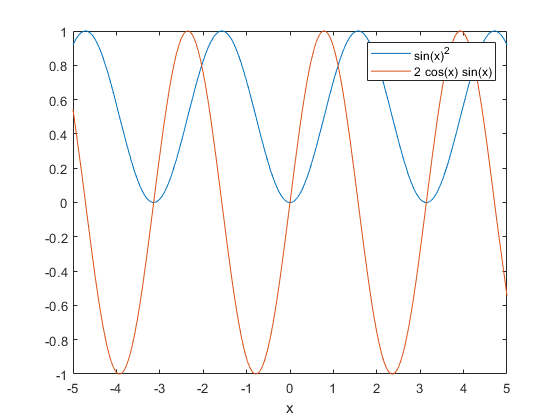

figure; fplot(f); hold on; fplot(diff(f));
legend; xlabel('x')

Calculate partial derivatives

syms x y
f = sin(x)^2 + cos(y)^2;% random function
% partial derivative with respect to y (x held fixed)
gradx=diff(f, x, 1), grady=diff(f,y,1)

$$gradx = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

$$grady = -2\,\cos\left(y\right)\,\sin\left(y\right)$$

diff(f, y, 2)% 2nd partial derivative with respect to y

$$ans = 2\,{\sin\left(y\right)}^{2}-2\,{\cos\left(y\right)}^{2}$$

Showcase a surface plot with tailored lighting and surface quality and a contour plot projection. Search MATLAB help for Analytical Plotting with Symbolic Math Toolbox (where this one came from)for more examples.

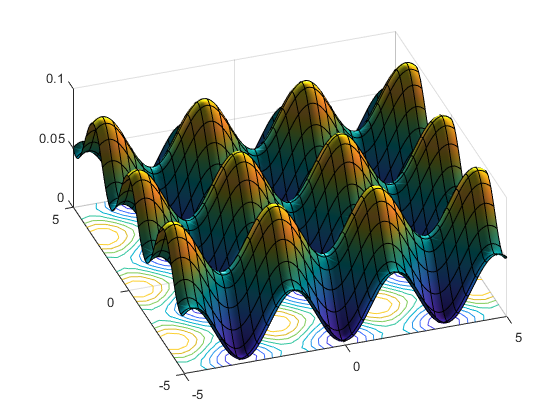

figure;

fsurf(f/20,'ShowContours','on')
set(camlight,'Color',[0.5 0.5 1]);
set(camlight('left'),'Color', [1 0.6 0.6]);
set(camlight('left'),'Color', [1 0.6 0.6]);
set(camlight('right'),'Color', [0.8 0.8 0.6]);
material shiny
view(-19,56)

Use the following to check your homework in Math 222 or whatever

f= x^2*exp(x)% another random function

$$f = x^{2}\,{\mathrm{e}}^{x}$$

int(f)% indefinite integral

$$ans = {\mathrm{e}}^{x}\,\left(x^{2}-2\,x+2\right)$$

int(f,x,0,1) % definite integral

$$ans = \mathrm{e}-2$$

taylor(f,x,1) % Taylor series about x=1

$$ans = \mathrm{e}+3\,\mathrm{e}\,\left(x-1\right)+\frac{7\,\mathrm{e}\,{\left(x-1\right)}^{2}}{2}+\frac{13\,\mathrm{e}\,{\left(x-1\right)}^{3}}{6}+\frac{7\,\mathrm{e}\,{\left(x-1\right)}^{4}}{8}+\frac{31\,\mathrm{e}\,{\left(x-1\right)}^{5}}{120}$$

## **Important caveat**

A computer can only do (historically) what it is asked to do. It is a tool, not a substitute for understanding of math and physics or other things. You will often tell it non-sensical things and have to figure out what YOU did wrong. The power of computerized math for a novice is learning "computational thinking," meaning how to think straight. If you can tell someone in simple terms something about physics, you understand it. If you can tell a computer to help you compute something in physics, you understand the physics.

That said, a computer can do things a human cannot do in a sensible amount of time, even in their lifetime!

Someday, and to an extent that day is upon us, computers using artificial intelligence techniques, will out think us too. But leaving learning to the computers is not an option at present for the architects of the future!